run thesis_aggregated_eval.mlx

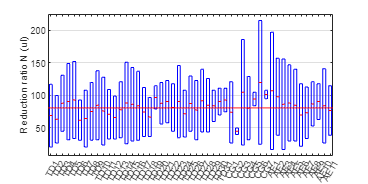

pathfig = 'C:\Users\u0130154\MATLAB\projects\seasize\thesis_figure';
pathpng = 'C:\Users\u0130154\OneDrive - KU Leuven\PhD\_writing\_thesis\phdthesis\chapters\actuatordesign\image';

%% Plot a boxplot of the feasible gearbox ratios
[feasresults, feasfig]=gearevals.feasableBoxplot(pat);
fig=figure(feasfig);
hold on
yline(81, 'r', LineWidth=1)
% Get handle to the current axes
ax = gca;
% Rotate x-axis labels by 45 degrees
set(ax, 'XTickLabelRotation', 60);
set(ax, 'FontSize', 7);

fig.Units = 'inches';
fig.Position = [0, 0, 6, 3];
title('')

% Save the figure as PNG
%savefig([pathfig '\aggrfeas' ])
%export_fig([pathpng '\aggrfeas.png' ], '-png', '-r300', '-nocrop', '-transparent')

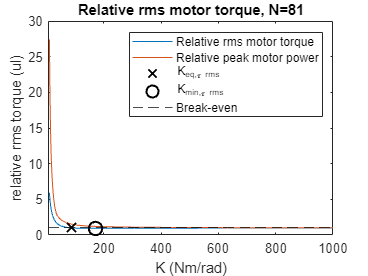

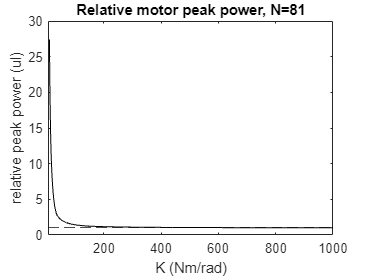

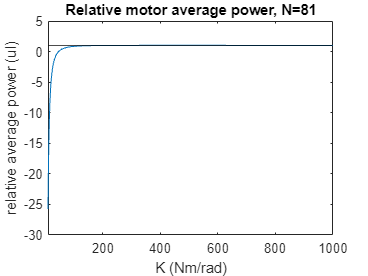

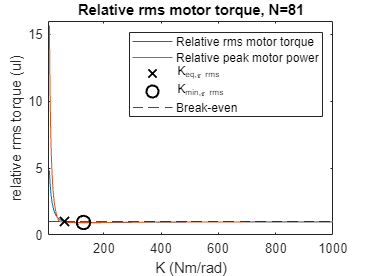

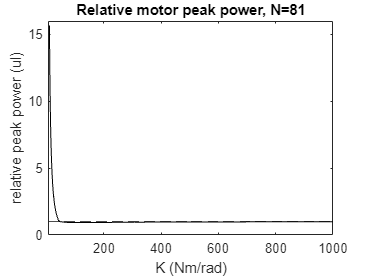

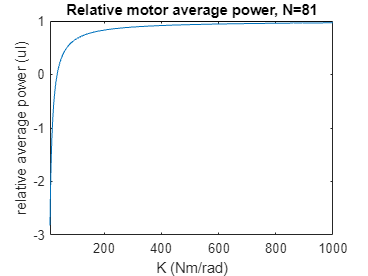

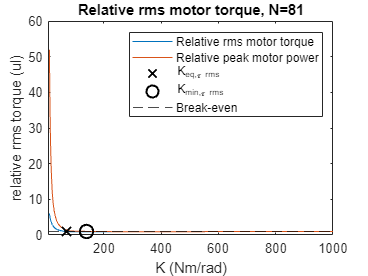

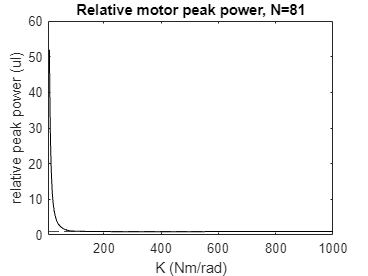

clear results_sel figsel
for i = 1:nr
    clear temp_result temp_fig
    [temp_result, temp_fig]=gearevals(i).plotSelected('N', 81, 'K', [10 1000 1000]);
    results_sel{i} =temp_result;
    figsel{i} = temp_fig;
end

for i = 1:nr
    clear temp_result
    temp_result = results_sel{i};
    Keqtrm(i) = temp_result.K_be_rms_tor;
    Kmintrms(i) = temp_result.K_min_rms_tor;
    KeqPpk(i) = temp_result.K_be_pk_p;
    KminPpk(i) = temp_result.K_min_pk_p;
end
boxplot([Keqtrm;Kmintrms;KeqPpk;KminPpk]', Labels={'$$K_{eq,\tau rms}$$', '$$K_{min,\tau rms}$$', '$$K_{eq,P\,max}$$', '$$K_{min,P\,max}$$'});
ylabel('$K$\,(Nm/rad)', "Interpreter","latex");
ax=gca

ax =   Axes with properties:

             XLim: [0.5000 4.5000]
             YLim: [-3.1802 919.0360]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1929 0.7750 0.7321]
            Units: 'normalized'

  Show all properties


ax.TickLabelInterpreter= 'latex';
grid on
fig=gcf

fig =   Figure (345) with properties:

      Number: 345
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


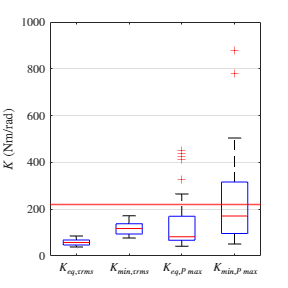

fig.Units = 'inches';
fig.Position = [0, 0, 3, 3];
title('')
ylim([0 1000]);
yline(220, 'r', LineWidth=1);
set(gca,'XGrid','off','YGrid','on');

% Save the figure as PNG
%savefig([pathfig '\aggrstiff' ])
%export_fig([pathpng '\aggrstiff.png' ], '-png', '-r300', '-nocrop', '-transparent')



Kstats=[meanstdminmaxCV(Keqtrm)'...
    meanstdminmaxCV(Kmintrms)' ...
    meanstdminmaxCV(KeqPpk)' ...
    meanstdminmaxCV(KminPpk)']

t3 = 21.8018

t3 = 44.0991

t3 = 102.5676

t3 = 220.4955

Kstats =    58.4979  118.0585  142.3964  235.7808
   57.5676  117.0270   81.8468  171.0360
   21.8018   44.0991  102.5676  220.4955
   13.2823   26.6172  120.6373  191.5899
   38.7387   77.3874   41.7117   51.6216
   85.3153  172.5225  449.0090  877.1171
    0.2271    0.2255    0.8472    0.8126
    0.0621    0.0725    1.4886    1.7654
   49.0000   49.0000   40.0000   36.0000
